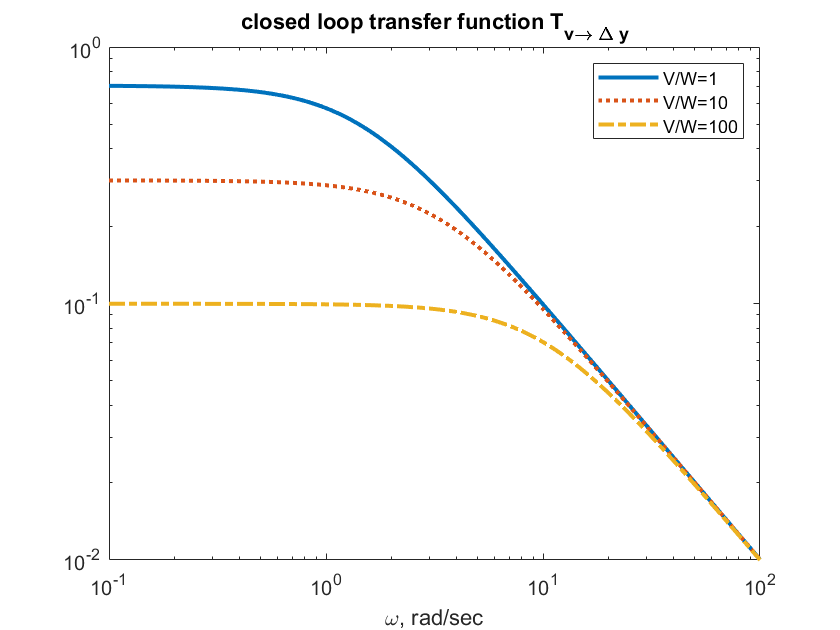

omega = logspace(-1,2,200);

% plant
A = 1;C=1;
B = 1;

% noise covariances
V1=1;W1=1;

E1 = A * W1 / (C^2) + sqrt((A*W1/(C^2))^2 + (V1*W1) / (C^2));

% calculate optimal observer gain
L1 = E1 *C / W1;

% closed loop disturbance response
sys1 = tf(C,[1, -(A -L1*C)]);
[mag1,phase1] = bode(sys1,omega);

% noise covariances
V2=1;W2=.1;

E2 = A * W2 / (C^2) + sqrt((A*W2/(C^2))^2 + (V2*W2) / (C^2));

% calculate optimal observer gain
L2 = E2 *C / W2;

% closed loop disturbance response
sys2 = tf(C,[1, -(A -L2*C)]);
[mag2,phase2] = bode(sys2,omega);


% noise covariances
V3=1;W3=.01;

E3 = A * W3 / (C^2) + sqrt((A*W3/(C^2))^2 + (V3*W3) / (C^2));

% calculate optimal observer gain
L3 = E3 *C / W3;

% closed loop disturbance response
sys3 = tf(C,[1, -(A -L3*C)]);
[mag3,phase3] = bode(sys3,omega);

loglog(omega,squeeze(mag1),'-',omega,squeeze(mag2),':',omega,squeeze(mag3),'-.')
title('closed loop transfer function T_{v\rightarrow \Delta y}')
xlabel('\omega, rad/sec')
legend('V/W=1','V/W=10','V/W=100')
set(findall(gcf,'type','line'),'linewidth',2)

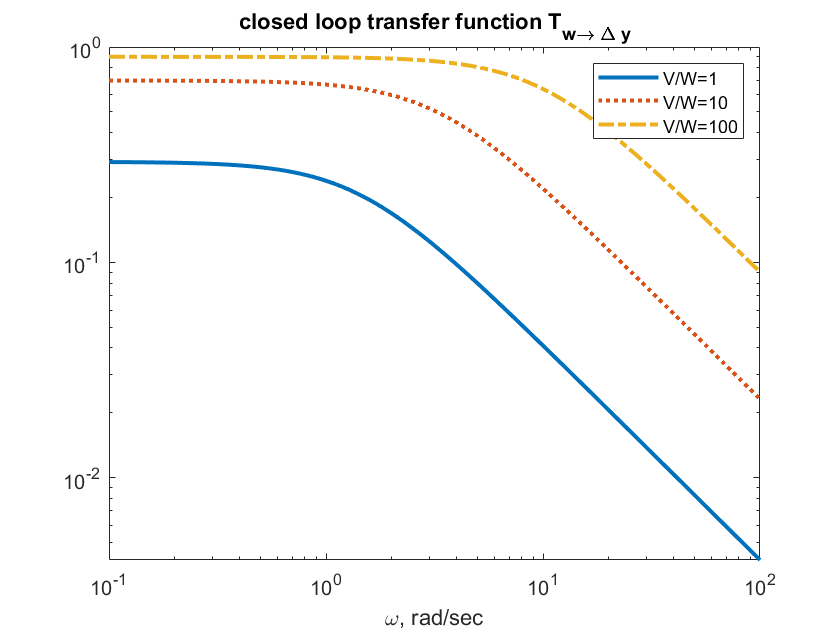




% closed loop noise response
[mag1,phase1] =  bode(tf(C*L1,[1,-(A - L1*C)]), omega);
[mag2,phase2] =  bode(tf(C*L2,[1,-(A - L2*C)]), omega);
[mag3,phase3] =  bode(tf(C*L3,[1,-(A - L3*C)]), omega);

figure(2)
clf

loglog(omega,squeeze(mag1) ,'-',omega,squeeze(mag2),':',omega,squeeze(mag3),'-.')
title('closed loop transfer function T_{w\rightarrow \Delta y}')
xlabel('\omega, rad/sec')
legend('V/W=1','V/W=10','V/W=100')
set(findall(gcf,'type','line'),'linewidth',2)

simulate response to noise inputs

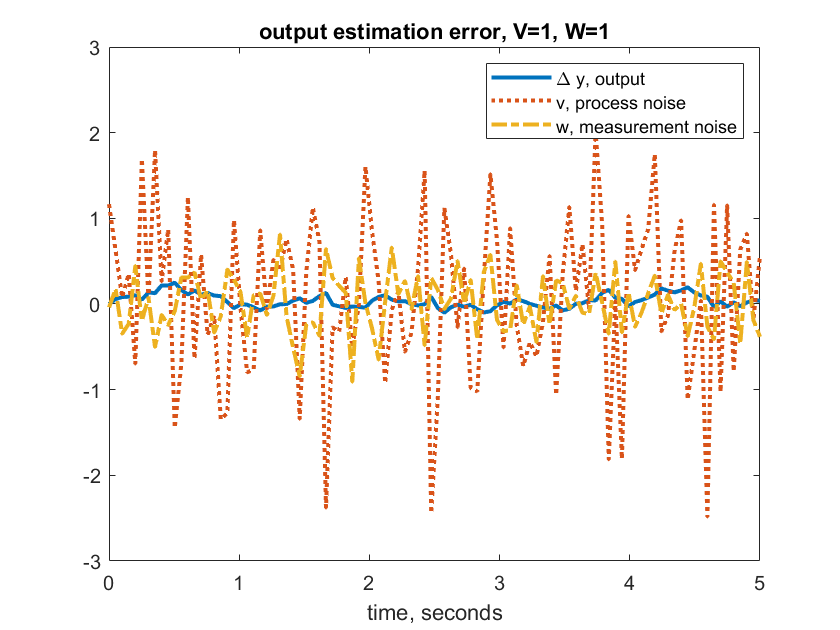

randn('seed',0);
t = linspace(0,5,100);
vnoise = randn(size(t));
wnoise = randn(size(t));

% state matrices of the closed loop system
% mapping [v;w] to Delta_y
Abig =  A - L1 * C;
Bbig =  [1, - L1];
Cbig =  C;
Dbig =  [0,0];

v = sqrt(V2)*vnoise;
w = sqrt(W2)*wnoise;

y = lsim(Abig,Bbig,Cbig,Dbig,[v' w'],t);

figure(3)
clf

plot(t,y,'-',t,v,':',t,w,'-.')
axis([0 5 -3 3])
xlabel('time, seconds')
title(['output estimation error, V=',num2str(V1),', W=',num2str(W1)])
legend('\Delta y, output','v, process noise',...
    'w, measurement noise')
set(findall(gcf,'type','line'),'linewidth',2)

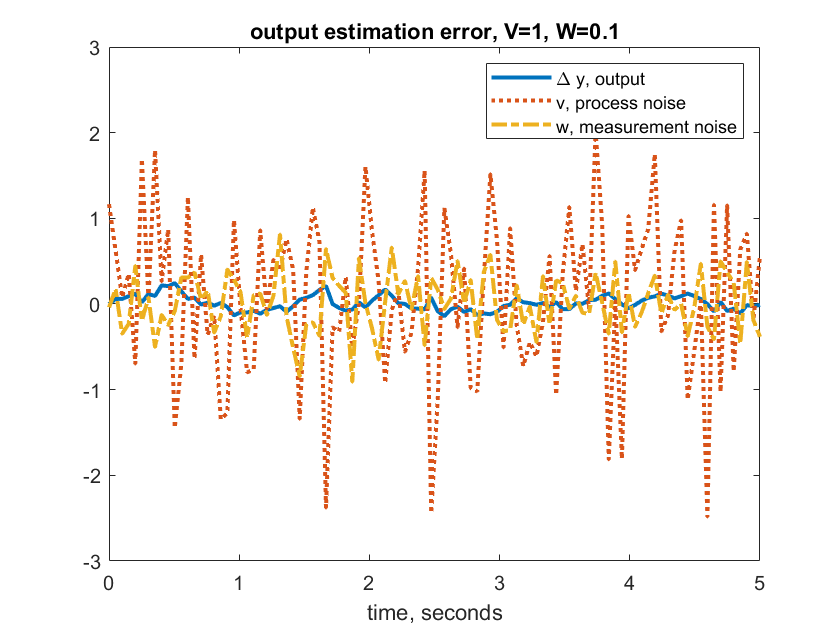


% state matrices of the closed loop system mapping
% [v;w] to Deltay
Abig =  A - L2 * C;
Bbig =  [1, - L2];
Cbig =  C;
Dbig =  [0,0];

v = sqrt(V2)*vnoise;
w = sqrt(W2)*wnoise;

y = lsim(Abig,Bbig,Cbig,Dbig,[v' w'],t);

figure(4)
clf

plot(t,y,'-',t,v,':',t,w,'-.')
axis([0 5 -3 3])
xlabel('time, seconds')
title(['output estimation error, V=',num2str(V2),', W=',num2str(W2)])
legend('\Delta y, output','v, process noise',...
    'w, measurement noise')
set(findall(gcf,'type','line'),'linewidth',2)

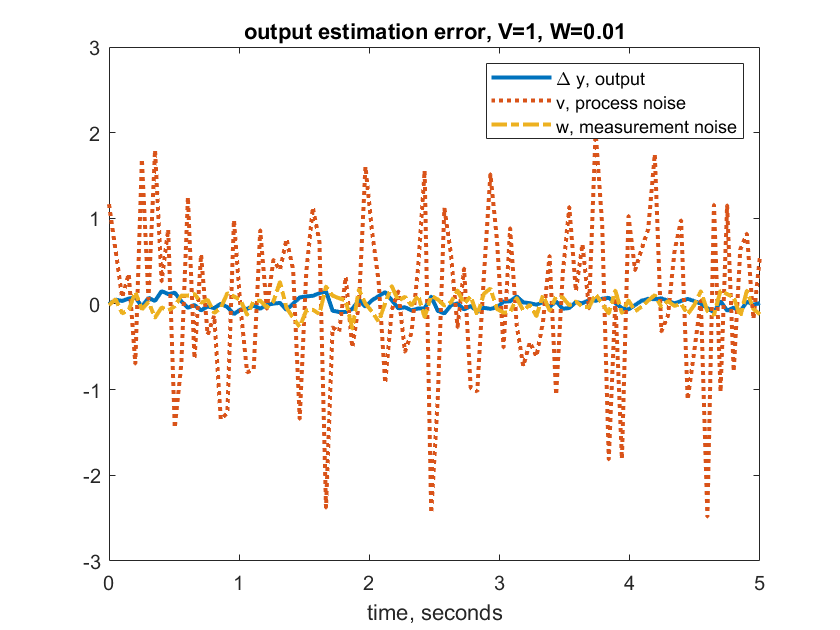



% state matrices of the closed loop system mapping
% [v;w] to Deltay
Abig =  A - L3 * C;
Bbig =  [1, - L3];
Cbig =  C;
Dbig =  [0,0];

v = sqrt(V3)*vnoise;
w = sqrt(W3)*wnoise;

y = lsim(Abig,Bbig,Cbig,Dbig,[v' w'],t);

figure(5)
clf

plot(t,y,'-',t,v,':',t,w,'-.')
axis([0 5 -3 3])
xlabel('time, seconds')
title(['output estimation error, V=',num2str(V3),', W=',num2str(W3)])
legend('\Delta y, output','v, process noise',...
      'w, measurement noise')  
set(findall(gcf,'type','line'),'linewidth',2)  

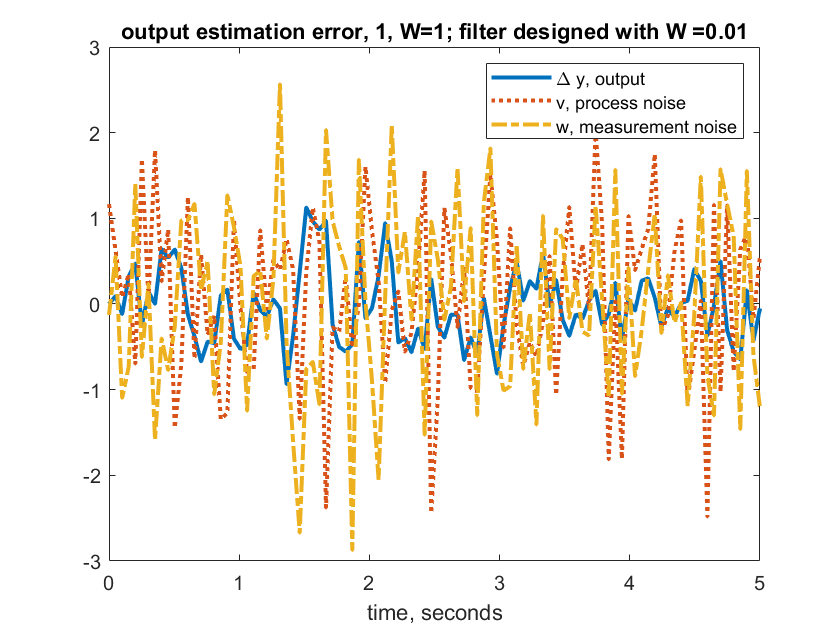


% simulate the response of on observer designed for clean
% measurements on a system with noisy measurements

figure(6)
clf

Abig =  A - L3 * C;
Bbig =  [1, - L3];
Cbig =  C;
Dbig =  [0,0];

v = sqrt(V3)*vnoise;
w = sqrt(W1)*wnoise;

y = lsim(Abig,Bbig,Cbig,Dbig,[v' w'],t);
plot(t,y,'-',t,v,':',t,w,'-.')
axis([0 5 -3 3])
xlabel('time, seconds')
title(['output estimation error, ',num2str(V1),', W=',num2str(W1),...
             '; filter designed with W =',num2str(W3)])
legend('\Delta y, output','v, process noise',...
      'w, measurement noise')
set(findall(gcf,'type','line'),'linewidth',2)